%Using the Matlab Symbolic Toolbox to solve for properties of parametric
%curves
clc, clear all

%For this demo code, we will solve for the parametric circle that is
%presented in Robo Night 1

%First we must define the symbolic variables we will being using
syms t w omega v_l v_r d a b

assume(t, {'real', 'positive'}) % parameter t should be real
assume(a, {'real', 'positive'}) % parameter a should be real
assume(b, {'real', 'positive'}) % parameter b should be real
assume(w, {'real', 'positive'})
assume(omega, 'real')
assume(v_l, 'real')
assume(v_r, 'real')
assume(d, {'positive', 'real'})
assumeAlso((w * t) < (2 * pi))
assumeAlso((w * t) > 0)

%Define the equation for the parametric circle. For clarity, I am first 
%creating individual equations for r in the i, j, and k direction, 
%then packing them in one vector. In this case, we are
%creating a 1x3 vector that has symbolic equations for the i, j, and k
%components of the equation, respectively. Note that the k component in
%this case is just equal to 0. We use 0*u because if we substitute a vector
%of numerical values in for the symbolic u at a later time, the dimensions
%of the vector will be consistent.
ri=a*cos(w * t);
rj=b*sin(w * t);
rk=0*t;
r=[ri,rj,rk]

$$r = \left(\begin{array}{ccc} a\,\cos\left(t\,w\right) & b\,\sin\left(t\,w\right) & 0 \end{array}\right)$$


%to take the derivative, we use the diff function in Matlab, with the
%inputs being diff(function,variable to differentiate)
dr=diff(r,t);
v = dr

$$v = \left(\begin{array}{ccc} -a\,w\,\sin\left(t\,w\right) & b\,w\,\cos\left(t\,w\right) & 0 \end{array}\right)$$

speed = norm(v)

$$speed = \sqrt{a^{2}\,w^{2}\,{\left|\sin\left(t\,w\right)\right|}^{2}+b^{2}\,w^{2}\,{\left|\cos\left(t\,w\right)\right|}^{2}}$$

T_hat=simplify(dr./norm(dr))

$$T\_hat = \left(\begin{array}{ccc} -\frac{a\,\sin\left(t\,w\right)}{\sqrt{a^{2}\,{\sin\left(t\,w\right)}^{2}-b^{2}\,{\sin\left(t\,w\right)}^{2}+b^{2}}} & \frac{b\,\cos\left(t\,w\right)}{\sqrt{a^{2}\,{\sin\left(t\,w\right)}^{2}-b^{2}\,{\sin\left(t\,w\right)}^{2}+b^{2}}} & 0 \end{array}\right)$$


%Next, we want to find the unit normal vector
dT_hat=simplify(diff(T_hat,t))

$$dT\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{a\,b^{2}\,w\,\cos\left(t\,w\right)}{\sigma_{1}} & -\frac{a^{2}\,b\,w\,\sin\left(t\,w\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(-a^{2}\,{\cos\left(t\,w\right)}^{2}+a^{2}+b^{2}\,{\cos\left(t\,w\right)}^{2}\right)}^{3/2} \end{array}$$

omega = simplify(cross(T_hat, dT_hat))

$$omega = \left(\begin{array}{ccc} 0 & 0 & \frac{a\,b\,w}{a^{2}\,{\sin\left(t\,w\right)}^{2}-b^{2}\,{\sin\left(t\,w\right)}^{2}+b^{2}} \end{array}\right)$$

rotation_speed = simplify(norm(omega))

$$rotation\_speed = \frac{a\,b\,w}{\left|a^{2}\,{\sin\left(t\,w\right)}^{2}-b^{2}\,{\sin\left(t\,w\right)}^{2}+b^{2}\right|}$$

v_l = simplify(speed - (rotation_speed * (d / 2)))

$$v\_l = \sqrt{a^{2}\,w^{2}\,{\left|\sin\left(t\,w\right)\right|}^{2}+b^{2}\,w^{2}\,{\left|\cos\left(t\,w\right)\right|}^{2}}-\frac{a\,b\,d\,w}{2\,\left|a^{2}\,{\sin\left(t\,w\right)}^{2}-b^{2}\,{\sin\left(t\,w\right)}^{2}+b^{2}\right|}$$

v_r = simplify(speed + (rotation_speed * (d / 2)))

$$v\_r = \sqrt{a^{2}\,w^{2}\,{\left|\sin\left(t\,w\right)\right|}^{2}+b^{2}\,w^{2}\,{\left|\cos\left(t\,w\right)\right|}^{2}}+\frac{a\,b\,d\,w}{2\,\left|a^{2}\,{\sin\left(t\,w\right)}^{2}-b^{2}\,{\sin\left(t\,w\right)}^{2}+b^{2}\right|}$$


N_hat=simplify(dT_hat/norm(dT_hat))

$$N\_hat = \left(\begin{array}{ccc} -\frac{b\,\cos\left(t\,w\right)}{\sqrt{-a^{2}\,{\cos\left(t\,w\right)}^{2}+a^{2}+b^{2}\,{\cos\left(t\,w\right)}^{2}}} & -\frac{a\,\sin\left(t\,w\right)}{\sqrt{-a^{2}\,{\cos\left(t\,w\right)}^{2}+a^{2}+b^{2}\,{\cos\left(t\,w\right)}^{2}}} & 0 \end{array}\right)$$


%The unit binormal vector is found from the cross product of the unit
%tangent and unit normal
B_hat=simplify(cross(T_hat,N_hat))

$$B\_hat = \left(\begin{array}{ccc} 0 & 0 & 1 \end{array}\right)$$


%We can also find the curvature
kappa=norm(dT_hat)/norm(dr);
kappa=simplify(kappa)

$$kappa = \frac{a\,b}{\left(-a^{2}\,{\cos\left(t\,w\right)}^{2}+a^{2}+b^{2}\,{\cos\left(t\,w\right)}^{2}\right)\,\sqrt{a^{2}\,{\sin\left(t\,w\right)}^{2}-b^{2}\,{\sin\left(t\,w\right)}^{2}+b^{2}}}$$


%How about the Torsion? 
tau=-dot(N_hat,(diff(B_hat,t)/norm(dr)))

$$tau = 0$$

a_N = simplify(dot(a, N_hat))

Error using dot (line 32)
A and B must be same size.

a_T = simplify(dot(a, T_hat))

d = 0.235; % m
R = 1; % m
t_complete = 30; % s, time to complete a circle
w = (2 * pi) / t_complete
v_l_actual = double(subs(v_l)) % m/s
v_r_actual = double(subs(v_r)) % m/s

%% Print everything nicely labeled for screenshotting
tangent_vector = dr
unit_tangent_vector = T_hat
linear_velocity_vector = v
disp("As opposed to the circle, the scalar coefficients on are different for each dimension.")
unit_normal_vector = N_hat
angular_velocity_vector = omega
fprintf("As compared to the circle, the angular velocity vector is *way* more complicated to\nreflect the fact that elptical motion involves a constantly changing rotational speed")
left_wheel_velocity = v_l
right_wheel_velocity = v_r

## Graphs

a = 3.2;
b = 2.2;
w = 1.3; % alpha
d = 0.235; % m

ts = linspace(0, 2 * pi / w, 50);

% NB: If this section complains about too many input arguments, rerun the
% first section and don't worry about it.

calc_r = matlabFunction(subs(r));

calc_r = function_handle with value:
    @(t)[cos(t.*(1.3e+1./1.0e+1)).*(1.6e+1./5.0),sin(t.*(1.3e+1./1.0e+1)).*(1.1e+1./5.0),0.0]


all_rs = reshape([calc_r(ts), zeros(1, 49)], [50 3]);

all_rs =     3.2000         0         0
    3.1737    0.2813         0
    3.0953    0.5580         0
    2.9661    0.8256         0
    2.7882    1.0796         0
    2.5645    1.3158         0
    2.2987    1.5305         0
    1.9952    1.7200         0
    1.6589    1.8813         0
    1.2953    2.0117         0


xlims = [min([-1; all_rs(:, 1)]), max([1; all_rs(:, 1)])] * 1.25;

xlims =    -3.9918    4.0000


ylims = [min([-1; all_rs(:, 2)]), max([1; all_rs(:, 2)])] * 1.25;

ylims =    -2.7486    2.7486


zlims = [min([-1; all_rs(:, 3)]), max([1; all_rs(:, 3)])] * 1.25;

zlims =    -1.2500    1.2500


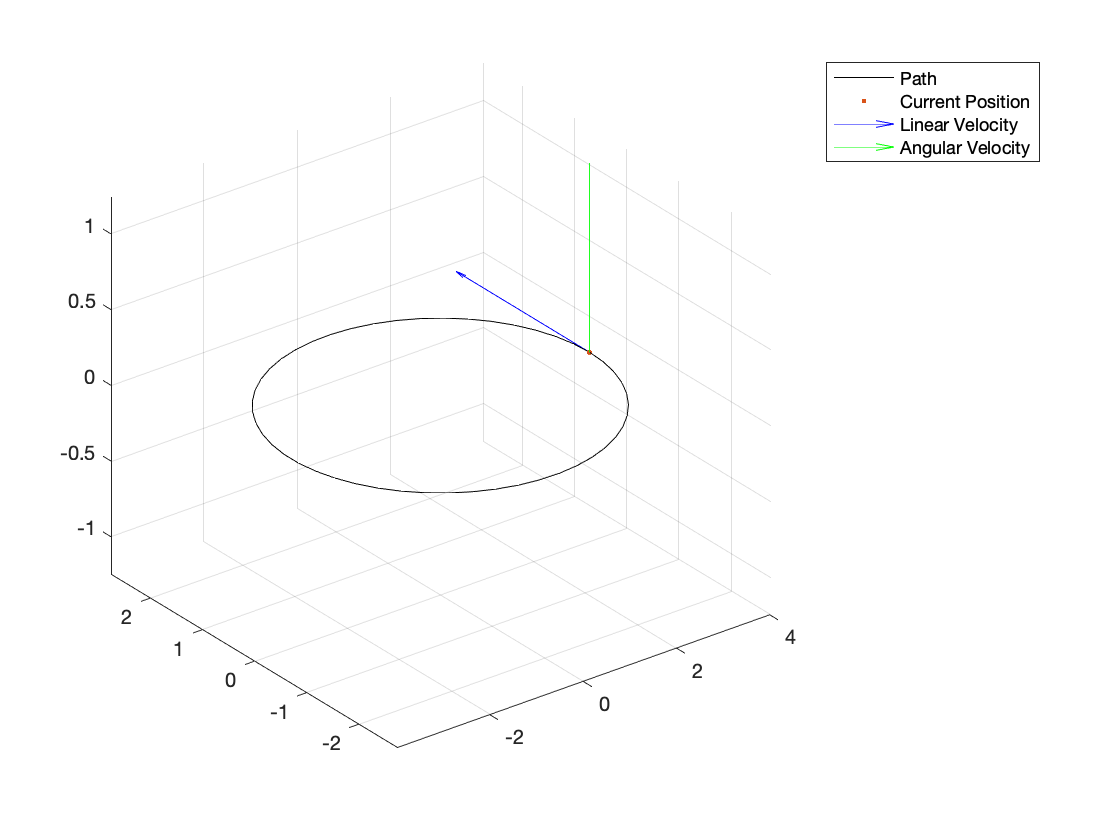


old_t = t;
for t_cur=ts
    t = t_cur;
    r_cur = double(subs(r));
     v_cur = double(subs(v));
     omega_cur = double(subs(omega));
     
     figure(1); clf; 
     plot3_sane(all_rs(ts <= t, :), 'k-'); hold on; grid on;
     plot3_sane(r_cur, '.');
     quiver3_sane(r_cur, v_cur, 'b');
     quiver3_sane(r_cur, omega_cur, 'g');
     legend(["Path", "Current Position", "Linear Velocity", "Angular Velocity"])
     xlim(xlims); ylim(ylims); zlim(zlims);
     drawnow;
    hold off;
end

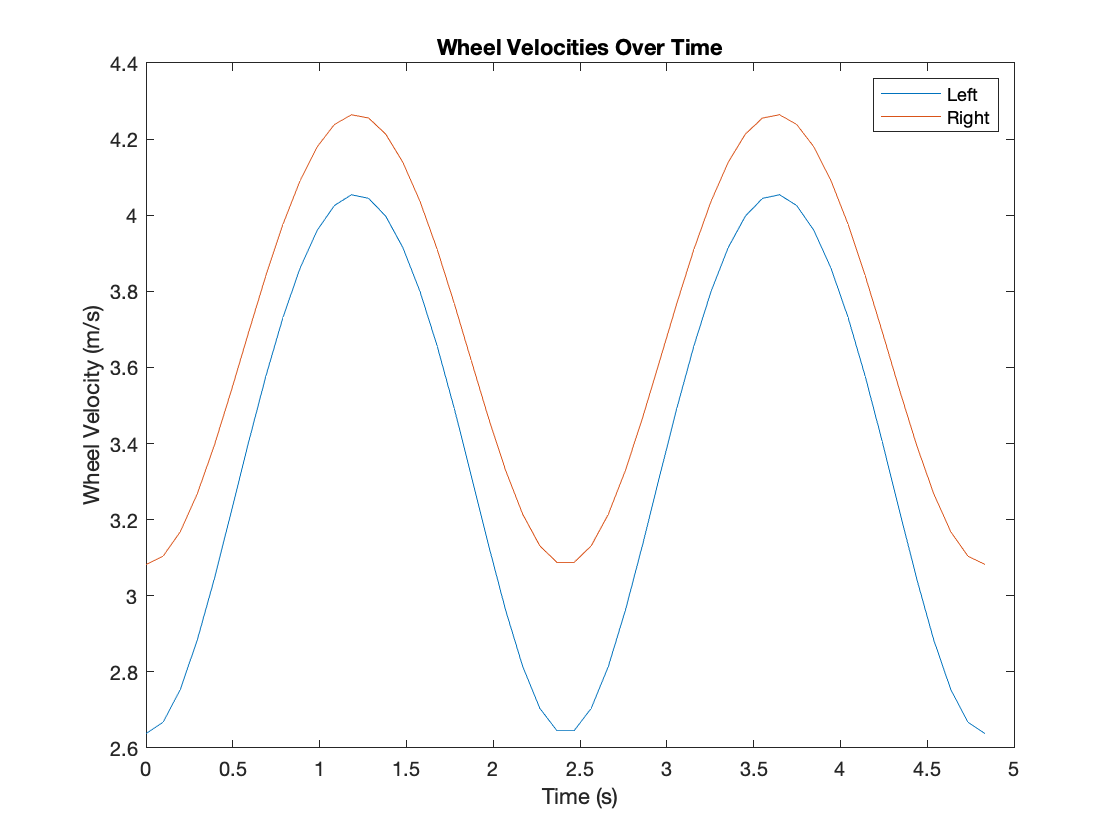

t = old_t;

figure(2); clf;

calc_v_l = matlabFunction(subs(v_l));
calc_v_r = matlabFunction(subs(v_r));

plot(ts, calc_v_l(ts)); hold on;
plot(ts, calc_v_r(ts));
xlabel("Time (s)")
ylabel("Wheel Velocity (m/s)")
title("Wheel Velocities Over Time")
legend("Left", "Right")
hold off;

function quiver3_sane(start, len, style)
    quiver3(start(:, 1), start(:, 2), start(:, 3), len(:, 1), len(:, 2), len(:, 3), style);
end

function plot3_sane(points, style)
    plot3(points(:, 1), points(:, 2), points(:, 3), style)
end